# Week 3: Ridgid Motion and Diagram Analysis

Demargio Glanville, WPI Graduate Student, ddglanville@WPI.edu

## Introduction

For this assignment, the goal was to apply knowledge of Rotations and Homogeneous Transformations.

For the first problem, 2-15, asked for a rotation matrix $R^2_3$ given $R_2^1$ and $R_3^1$. Then rotation matrix found by rearranging a formula which related all three of the matrices. As a check, the result was then used in the orignal formula.

The second problem, 2-38, gave a diagram for which the homogeneous transformations, $H_1^0$, $H_2^0$, $H_3^0$, $H_4^0$, and $H_2^3$. Using the dimensions and Frame orientations given in the diagram, the rotation matrices were solved.

The last problem was a diagram of a robot which was to analyzed and then solved for $H_4^0$. The Homogeneous Transformation was solved step by step from one frame to the next until arriving at $O_4$.

## Materials and Methods

### Nomenclature:

- $S_{\theta ,\phi }$         Sine with relation to $\theta$ or $\phi$

- $C_{\theta ,\phi }$        Cosine with relation to $\theta$ or $\phi$

- $R_j^i$           Rotational Matrix in frame $j$ in the coordinate system of $i$

- $R_{i,j}$          Basic Rotation Matrix about $i$ axis and by$j$ radians

- $H_j^i$          Homogeneous Matrix in frame $j$ in the coordinate system of $i$

- $O$            Coordinate Frame

- $d$             Displacement vector

- $\theta ,\phi ,\varphi ,\alpha$ Angle in radians

clear % Removing previously existing variables.

% Sybmbolic Variables
syms alpha theta psi phi d

% Basic Rotation Matricies
Rx = [1 0 0; 
       0 cos(theta) -sin(theta);
       0 sin(theta) cos(theta)];

Ry = [cos(theta) 0 sin(theta); 
       0 1 0;
       -sin(theta) 0 cos(theta)];

Rz = [cos(theta) -sin(theta) 0; 
       sin(theta) cos(theta) 0;
       0 0 1];
Ri = [1 0 0;
      0 1 0;
      0 0 1];

### Process:

####     2-15

Problem 2-15 provided two rotation matrices, $R_2^1$ and $R_3^1$, listed below. Given these matrices, a third matrix, $R_3^2$ was to be derived.

$R_2^1 =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \frac{1}{2} & -\frac{\sqrt{3}}{2}\\
0 & \frac{\sqrt{3}}{2} & \frac{1}{2}
\end{array}\right\rbrack$                                                                                                                                                                    **(Matrix 1)**

$R_3^1 =\left\lbrack \begin{array}{ccc}
0 & 0 & -1\\
0 & 1 & 0\\
1 & 0 & 0
\end{array}\right\rbrack$                                                                                                                                                                    **(Matrix 2)**

$R_3^1$ is rotation matrix of Frame $O_3$ with respect to $O_1$. The Rotation matrix can also be denote as the following equation:

         $R_3^1 =R_2^1 R_3^2$                                                                                                                                                                        (**Equation 1**)

Equation 1 was the relationship amongst the three matrices. This equation was the rearraged to solve for $R_3^2$ by multiplying both sides of the equation by the ${R_2^1 }^{-1}$. The result was the following equation:

$R_3^2 ={R_2^1 }^{-1} R_3^1$                                                                                                                                                                        (**Equation 2**)

Once Equation 2 was established, the inverse of $R_2^1$ had to be found. To determine the inverse of $R_2^1$, first a matrix of minors, ${R_2^1 }_m$, was made resulting in the following matrix:

${R_2^1 }_m =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \frac{1}{2} & \frac{\sqrt{3}}{2}\\
0 & -\frac{\sqrt{3}}{2} & \frac{1}{2}
\end{array}\right\rbrack$                                                                                                                                                                    **(Matrix 3)**

Then, a matrix of cofactors was applied and the matrix was transposed, producing an Adjugate. The result, was Matrix 3, the matrix of miniors. Then the resulting Adjugate, the matrix of minors in this case, was multiplied by the inverse of the determinate of Matrix 1, the orignal matrix. The determinate of the Matrix 1 was 1 thus, the inverse of Matrix 1 is Matrix 3. The result has been rewritten for clarity.

${R_2^1 }^{-1} =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & \frac{1}{2} & \frac{\sqrt{3}}{2}\\
0 & -\frac{\sqrt{3}}{2} & \frac{1}{2}
\end{array}\right\rbrack$                                                                                                                                                                    **(Matrix 4)**

The inverse matrix was then used in Equation 2 to solve for $R_3^2$. Afterwards, the results were double checked by using $R_3^2$ in Equation 1 and comparing this result to $R_3^1$.

####     2-38

Problem 2-38 asked for four homogeneous transformations given the diagram below.

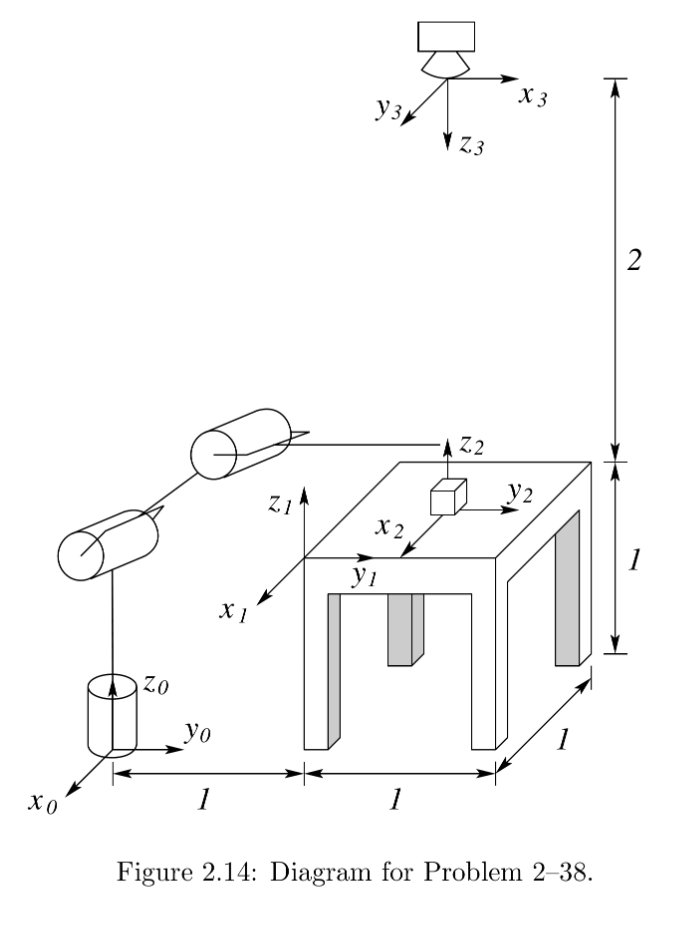

**(Figure 2.14)**

With figure 2.14, the homogeneous transformations,$H_1^0$,$H_2^0$, $H_3^0$, and $H_2^3$ could be solved using the related dimensions and relative rotations. A homogeneous transformation is a rigid motion, rotation then translation. The relation can be seen below.

$H=\left\lbrack \begin{array}{cc}
R & d\\
0 & 1
\end{array}\right\rbrack$                                                                                                                                             (**Equation 2.67)**

In equation  2.67, $R$ represents the rotational matrix (3x3 matrix) and $d$ is the displacement vector (3x1 matrix). In its expanded form, equation 2.67 would actually be a 4x4 matrix, which will be demonstrated further down.

In the case of $H_1^0$, the $O_0$ frame was not rotated to reorient the frame thus, an Identity matrix can be used to represent the lack of rotation. Although the frame did not need any rotations, the frame is located at a rotary joint thus, the possible rotation of the joint, around the Z- axis,  also had to be accounted for which resulted in the folowing equation:

$R_1^0 =\left\lbrack \begin{array}{ccc}
C_{\theta }  & {-S}_{\theta }  & 0\\
S_{\theta }  & C_{\theta }  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \bullet \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack \Rightarrow \left\lbrack \begin{array}{ccc}
C_{\theta }  & {-S}_{\theta }  & 0\\
S_{\theta }  & C_{\theta }  & 0\\
0 & 0 & 1
\end{array}\right\rbrack =R_1^0$                                                                                                           (**Equation 3)**

With the Rotation matrix defined, the displacement vector was next. The displacement vector holds the distance on each axis from the coordinate system to the frame. in the case of $H_1^0$, $O_0$ is 1 meter from $O_1$ in the direction of the z-axis and 1 meter in the direction of the y-axis as well. With this the Displacement vector for $H_1^0$ was found to be the matrix below.

$d_1^0 =\left\lbrack \begin{array}{c}
0\\
1\\
1
\end{array}\right\rbrack$                                                                                                                                                          **(Matrix 5)**

With everything defined, they were used in equation 2.67 to produce the solution to $H_1^0$.

The same process was repeated to solve for $H_2^0$. Once again, there was not any rotation to reorient the frame. The rotation of the joint about the Z-axis was again accounted for which resulted in the same equation as Equation 3 thus, $R_2^0 =$$R_1^0$. The displacement for $O_0$ and $O_2
$ was different from $d_1^0$. From $O_0$ to $O_2
$ the displacement in the Z direction was the height of the table, 1 meter, plus the distance to the center of the cube, .1 meters. In the displacement to the cube in the Y direction was the distance to the table's edge 1 meter, plus the distance to the center of the table, .5 meters. Then the displacement in the X direction was the distance to the center of the table but, it was also negative in realation to $O_0$. All of this resulted in the following Matrix:

$d_2^0 =\left\lbrack \begin{array}{c}
-\ldotp 5\\
1\ldotp 5\\
1\ldotp 1
\end{array}\right\rbrack$                                                                                                                                                        **(Matrix 9)**

The Rotation matrix and displacement vector were used in equation 2.67 to produce the solution to $H_2^0$.

Then the homogeneous transformation was found for $H_3^0$. The frame $O_0$ was rotated to match $O_3$. First, the frame had to be rotated about the Z axis$\alpha \;$degrees then rotated about the X axis, $\varphi$ degrees. Once these were done, the rotation in the joint was accounted for. The equation below will result in the Rotation Matrix $R_3^0$.

$R_3^0 =\left\lbrack \begin{array}{ccc}
C_{\theta }  & {-S}_{\theta }  & 0\\
S_{\theta }  & C_{\theta }  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \bullet \left(\left\lbrack \begin{array}{ccc}
C_{\phi }  & {-S}_{\phi }  & 0\\
S_{\phi }  & C_{\phi }  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \bullet \left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & C_{\varphi }  & {-S}_{\varphi } \\
0 & S_{\varphi }  & C_{\varphi } 
\end{array}\right\rbrack \right)$                                                                                                               (**Equation 4)**

The displacement vector for $O_3$ was similar to $d_2^0$ because $O_3$ is located directly above $O_2$. For $O_3$ the displacement from $O_0$ along the X axis was still negative .5 meters. The displacement along the Y axis remained the same at 1.5 meters in the positive direction. The displacement along the Z axis was different since the $O_3$ was located 2 meters above the table thus, the displacement along the Z axis was 3 meters. All of this resulting in the following vector.

$d_3^0 =\left\lbrack \begin{array}{c}
-\ldotp 5\\
1\ldotp 5\\
3
\end{array}\right\rbrack$                                                                                                                                                      **(Matrix 10)**

Then the components were once again assembled using Equation 2.67.

The last transformation was $H_2^3$ . The rotation matrix from $O_3$ to $O_2$ is similar in process to $R_3^0$ however, reversed. Frame 3 is first rotated about the X axis then rotated about the Z axis. Frame three is not located at a joint and does not have the abiltiy to rotated thus there is no need to account for joint motion. This results in the following equation:

$R_2^3 =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & C_{\varphi }  & {-S}_{\varphi } \\
0 & S_{\varphi }  & C_{\varphi } 
\end{array}\right\rbrack \bullet \left\lbrack \begin{array}{ccc}
C_{\phi }  & {-S}_{\phi }  & 0\\
S_{\phi }  & C_{\phi }  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$                                                                                                                               (**Equation 5)**

The displacement for $H_2^3$ can be found from Figure 2.14. Relative to one another the only displacemen is along the Z axis since Frame 3 is located directedly above Frame 2. The displacement along the Z axis was 1.9 meters in the positive direction, accounting for the dimensions of the cube.

  $d_2^3 =\left\lbrack \begin{array}{c}
0\\
0\\
1\ldotp 9
\end{array}\right\rbrack$                                                                                                                                                       **(Matrix 11)**

With the equations established, they were put together using equation 2.67.

####     SCARA Analysis

The final problem gave us a diagram of a SCARA robot. From the diagram, the transformation $H_4^0$ was to be solved for.

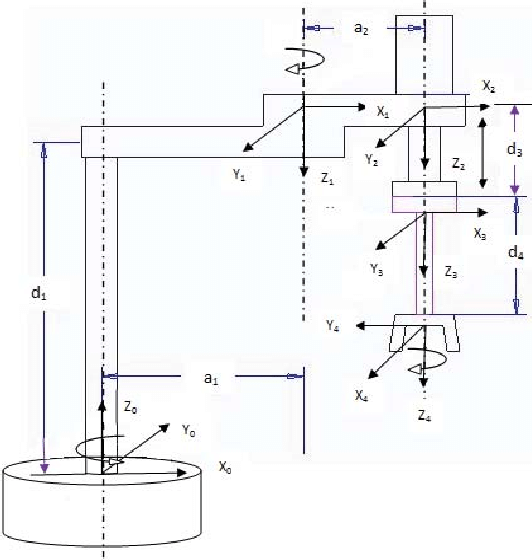 

**(Figure 1)**

The first step was to simplify Figure 1 into its very base concept. 

 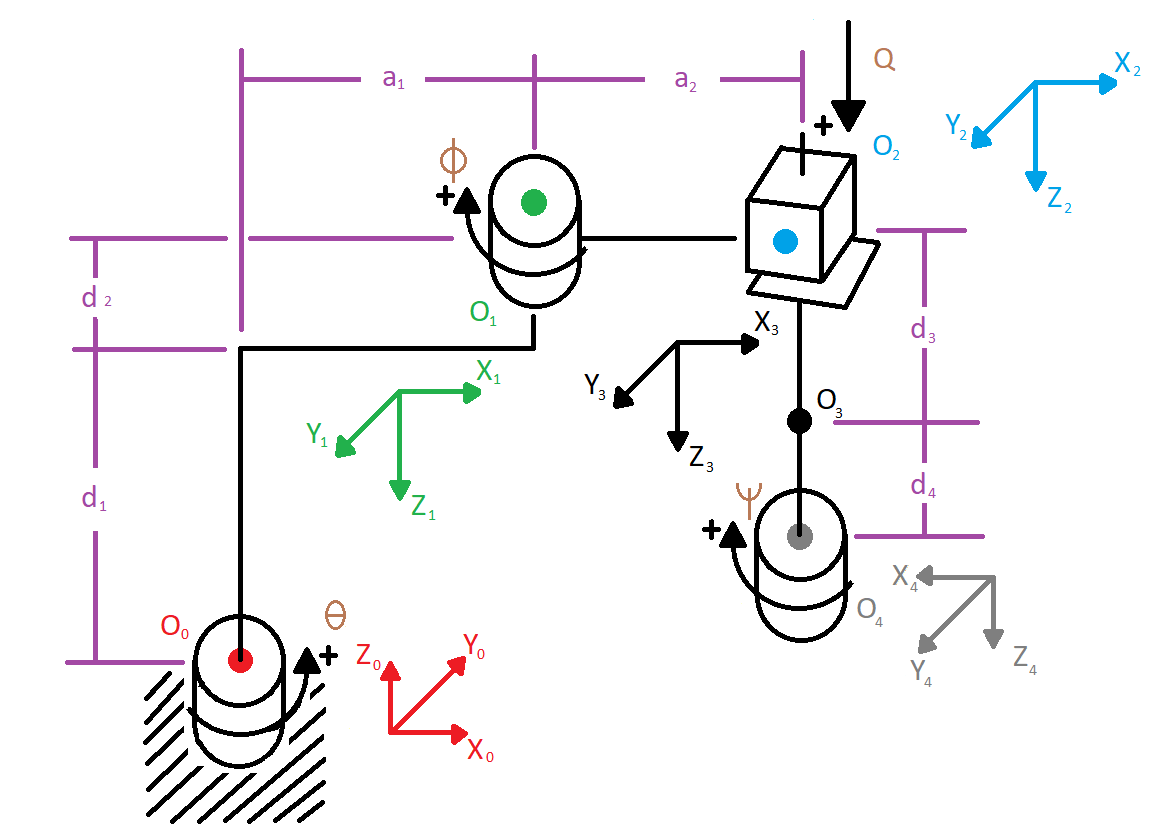

**(Figure 2)**

As seen in the figure above, Joint $O_0$ is a rotational joint about the Z-axis. Its frame is represented in red. Joint $O_1$ is also a rotational joint about the Z- axis but the Z axis is in the opposite direction.The frame for $O_1$is represented in green. $O_1$ is offset from $O_0$ by links $d_1$, $d_2$, and $a_1$. $O_2$ is a prismatic joint only moving in the Z-axis. The frame for $O_2$ is blue. Connecting $O_2$ to $O_1$  is link $a_2$. $O_3$ is a connection rather than a joint. It does not add any motion, it only acts as a connection between link $d_3$ to the prismatic joint.The frame for $O_3$ is represented in black.$O_4$ is the end affector which is a rotational joint and is offset from $O_3$ by link $d_4$. The frame for $O_4$ is represented in gray.

Using the diagram a homogeneous transformation from $O_0$ to $O_4$, $H_4^0$, was created. From the diagram, it was clear $H_4^0 =H_1^0 \;H_2^1 H_3^2 H_4^3$. With this, $H_1^0$ was the first to be solved for. First the rotational matrix was found. The Frame had to be rotated about the X axis $\varphi$ degrees. Then there was a need to account for the possible joint rotation,$\;\theta$, about the Z-axis.

$R_1^0 =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & C_{\theta }  & {-S}_{\theta } \\
0 & S_{\theta }  & C_{\theta } 
\end{array}\right\rbrack \bullet \left\lbrack \begin{array}{ccc}
C_{\varphi }  & {-S}_{\varphi }  & 0\\
S_{\varphi }  & C_{\varphi }  & 0\\
0 & 0 & 1
\end{array}\right\rbrack \Rightarrow \left\lbrack \begin{array}{ccc}
C_{\varphi }  & {-S}_{\varphi }  & 0\\
C_{\theta } S_{\varphi }  & C_{\varphi } C_{\theta }  & {-S}_{\theta } \\
S_{\varphi } S_{\theta }  & C_{\varphi } S_{\theta }  & C_{\theta } 
\end{array}\right\rbrack =R_1^0$                                                                                                                         **   (Equation 6)**

Then the displacement vector was solved. According to Figure 1, $a_1$ can lie between the x and y axis and will have has both x and y components while $d_1$ and $d_2$ have only z components. Thus the displacement vector was as follows:

$d_1^0 =\left\lbrack \begin{array}{c}
a_1 \sin \left(\theta \right)\\
a_1 \cos \left(\theta \right)\\
d_1 +d_2 
\end{array}\right\rbrack$                                                                                                                                                                       **(Matrix 12)**

After, the two are used in the general homogeneous transformation equation.

$H_1^0 =\left\lbrack \begin{array}{cccc}
C_{\varphi }  & {-S}_{\varphi }  & 0 & a_1 \sin \left(\theta \right)\\
C_{\theta } S_{\varphi }  & C_{\varphi } C_{\theta }  & {-S}_{\theta }  & a_1 \cos \left(\theta \right)\\
S_{\varphi } S_{\theta }  & C_{\varphi } S_{\theta }  & C_{\theta }  & d_1 +d_2 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$                                                                                                                                                         **(Matrix 13)**

When solving for the rotational matrix of $H_2^1$, it was seen frame $O_2$ is in the same orientation as frame $O_1$, thus the rotation can be represented with an identiy matrix. There is a need to account for the rotation in the joint of $O_1$ around the z axis.

$R_2^1 =\left\lbrack \begin{array}{ccc}
C_{\phi }  & {-S}_{\phi }  & 0\\
S_{\phi }  & C_{\phi }  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$                                                                                                                                                                    **(Matrix 14)**

As seen in Figure 1, similar to link $a_1$, $a_2$ can lie between the x and y axis and has x and y components thus, the displacement vector is as follows:

 $d_2^1 =\left\lbrack \begin{array}{c}
a_2 \mathrm{sin}\left(\phi \right)\\
a_2 \mathrm{cos}\left(\phi \right)\\
0
\end{array}\right\rbrack$                                                                                                                                                                      **(Matrix 15)**

The two were then used in equation 2.67.

$H_2^1 =\left\lbrack \begin{array}{cccc}
C_{\phi }  & {-S}_{\phi }  & 0 & a_2 \mathrm{sin}\left(\phi \right)\\
S_{\phi }  & C_{\phi }  & 0 & a_2 \mathrm{cos}\left(\phi \right)\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$                                                                                                                                                            **(Matrix 16)**

Then, solving for the rotational matrix of $H_3^2$, $O_2$ is a prismatic joint and does not rotate. Not only that, the frame is in the same orientation as $O_3$ thus, the entire rotation for $R_3^2$ can be represented by an identity matrix.

$R_3^2 =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$                                                                                                                                                                        **(Matrix 17)**

The displacement vector only has one element in the Z direction, the prismatic motion of joint $O_2$, $Q$, plus the displacement $d_3$ .

$d_3^2 =\left\lbrack \begin{array}{c}
0\\
0\\
Q+d_3 
\end{array}\right\rbrack$                                                                                                                                                                         **(Matrix 18)**

With rotation and displacement, the Homogeneous transformation, $H_3^2$, resulted in the following.

$H_3^2 =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & Q+d_3 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$                                                                                                                                                                   **(Matrix 19)**

Finally, solving for the rotational matrix of $H_4^3$, $O_3$ is a static connection which does not rotate thus the only rotation needed was the reorientation of the frame to $O_4$. This for this rotation, $O_3$ was rotated about its Z axis $\alpha$ degrees, producing the following matrix:

$R_4^3 =\left\lbrack \begin{array}{ccc}
C_{\alpha }  & {-S}_{\alpha }  & 0\\
S_{\alpha }  & C_{\alpha }  & 0\\
0 & 0 & 1
\end{array}\right\rbrack$                                                                                                                                                                    **(Matrix 20)**

The displacement from $O_3$ to $O_4$ is only along the Z axis and is represented in the following matrix:

$d_4^3 =\left\lbrack \begin{array}{c}
0\\
0\\
d_4 
\end{array}\right\rbrack$                                                                                                                                                                           **(Matrix 21)**

The two equations are used in 2.67 to produce $H_4^3$

$H_4^3 =\left\lbrack \begin{array}{cccc}
C_{\alpha }  & {-S}_{\alpha }  & 0 & 0\\
S_{\alpha }  & C_{\alpha }  & 0 & 0\\
0 & 0 & 1 & d_4 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$                                                                                                                                                                **(Matrix 22)**

## Results

####     2-15

The matricies and derived equations are check using a quick function, EqualTo.

Equation 2 produced the result,$R_3^2$, which was then checked for accuracy in the Fuction "EqualTo" which compares each element of results of Equation 1, $R_2^1 *R_3^2$. 

R12 = [1 0 0;
        0 sym(1/2) sym(-sqrt(3)/2);
        0 sym(sqrt(3)/2) sym(1/2)]; % The rotation matrix R of 2 with respect to 1

R13 = [0 0 -1;
       0 1 0;
       1 0 0]; % The rotation matrix R of 3 with respect to 1

R23 = inv(R12) * R13

$$R23 = \left(\begin{array}{ccc} 0 & 0 & -1\\ \frac{\sqrt{3}}{2} & \frac{1}{2} & 0\\ \frac{1}{2} & -\frac{\sqrt{3}}{2} & 0 \end{array}\right)$$


EqualTo(R23,R12,R13) % Checks matrix Equality

The Rotation Matrix of frame 3 with respect to frame 2 is correct.


clear R12 R13 R23

####     2-38

Using figure 2.14, Homogeneous transformations were found for$H_1^0$,$H_2^0$, $H_3^0$, and $H_2^3$ . The Function "TransformCombo' takes the Rotation matrix and the diplacement vector as inputs and outputs the Homogeneous Transformation Matrix.

R01 = Rz; % Equation 3
R02 = R01;
R03 = simplify(Rz*(subs(Rz,phi)*subs(Rx, psi))); % Equation 4
R32 = simplify(subs(Rx,psi)*subs(Rz,phi)); % Equation 5

d01 = [0;
       1;
       1]; % Matrix 5
d02 = [-.5;
       1.5;
       1.1]; % Matrix 9
d03 = [-.5;
       1.5;
       3]; % Matrix 10
d32 = [0;
       0;
       1.9]; % Matrix 11

First $H_1^0$

H01 = TransformCombo(R01,d01)

$$H01 = \left(\begin{array}{cccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0 & 0\\ \sin\left(\theta \right) & \cos\left(\theta \right) & 0 & 1\\ 0 & 0 & 1 & 1\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Then $H_2^0$

H02 = TransformCombo(R02,d02)

$$H02 = \left(\begin{array}{cccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0 & -\frac{1}{2}\\ \sin\left(\theta \right) & \cos\left(\theta \right) & 0 & \frac{3}{2}\\ 0 & 0 & 1 & \frac{11}{10}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$H_3^0$ requires the rotation angles $\phi =\frac{\pi }{2}$ and $\varphi =\pi$.

phi = pi/2; 
psi = pi;
R03 = simplify(subs(R03));
syms phi psi % Reverting symbolics for later use

H03 = TransformCombo(R03,d03)

$$H03 = \left(\begin{array}{cccc} -\sin\left(\theta \right) & \cos\left(\theta \right) & 0 & -\frac{1}{2}\\ \cos\left(\theta \right) & \sin\left(\theta \right) & 0 & \frac{3}{2}\\ 0 & 0 & -1 & 3\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$H_2^3$ requires the rotation angles $\phi =-\frac{\pi }{2}$ and $\varphi =\pi$.

phi = -pi/2; 
psi = pi;
R32 = simplify(subs(R32));
syms phi psi % Reverting symbolics for later use

H32 = TransformCombo(R32,d32)

$$H32 = \left(\begin{array}{cccc} 0 & 1 & 0 & 0\\ 1 & 0 & 0 & 0\\ 0 & 0 & -1 & \frac{19}{10}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

####     SCARA Analysis

Using Matrices 13, 16, 19, and 22 and the equation $H_4^0 =H_1^0 \;H_2^1 H_3^2 H_4^3$, $H_4^0$ was found. First each of the other Transformations wer found.

syms d1 d2 d3 d4 a1 a2 Q

R01 = Rx*subs(Rz,psi);
R12 = subs(Rz, phi);
R23 = Ri;
R34 = subs(Rz,alpha);

d01 = [a1*cos(theta);
       a1*sin(theta);
       d1 + d2];
d12 = [a2*cos(phi);
       a2*sin(phi);
       0];
d23 = [0;
       0;
       d3 + Q];
d34 = [0;
       0;
       d4];


psi = pi;
R01 = simplify(subs(R01));
syms psi

H01 = TransformCombo(R01,d01);

$$H01 = \left(\begin{array}{cccc} -1 & 0 & 0 & a_{1}\,\cos\left(\theta \right)\\ 0 & -\cos\left(\theta \right) & -\sin\left(\theta \right) & a_{1}\,\sin\left(\theta \right)\\ 0 & -\sin\left(\theta \right) & \cos\left(\theta \right) & d_{1}+d_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


H12 = TransformCombo(R12,d12);

$$H12 = \left(\begin{array}{cccc} \cos\left(\varphi \right) & -\sin\left(\varphi \right) & 0 & a_{2}\,\cos\left(\varphi \right)\\ \sin\left(\varphi \right) & \cos\left(\varphi \right) & 0 & a_{2}\,\sin\left(\varphi \right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


H23 = TransformCombo(R23,d23);

$$H23 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & Q+d_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


alpha = pi;
R34 = simplify(subs(R34));
syms alpha

H34 = TransformCombo(R34,d34);

$$H34 = \left(\begin{array}{cccc} -1 & 0 & 0 & 0\\ 0 & -1 & 0 & 0\\ 0 & 0 & 1 & d_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


H04 = simplify(H01*H12*H23*H34)

$$H04 = \left(\begin{array}{cccc} \cos\left(\varphi \right) & -\sin\left(\varphi \right) & 0 & a_{1}\,\cos\left(\theta \right)-a_{2}\,\cos\left(\varphi \right)\\ \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) & -\sin\left(\theta \right) & a_{1}\,\sin\left(\theta \right)-\sin\left(\theta \right)\,\left(Q+d_{3}\right)-d_{4}\,\sin\left(\theta \right)-a_{2}\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\\ \sin\left(\varphi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right) & d_{1}+d_{2}+\cos\left(\theta \right)\,\left(Q+d_{3}\right)+d_{4}\,\cos\left(\theta \right)-a_{2}\,\sin\left(\varphi \right)\,\sin\left(\theta \right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Values of links were esimated from the diagram and used in $H_4^0$.

d1 = 1000;
d2 = 20;
d3 = 300;
d4 = 350;

a1 = 500;
a2 = 350;

H04 = subs(H04)

$$H04 = \left(\begin{array}{cccc} \cos\left(\varphi \right) & -\sin\left(\varphi \right) & 0 & 500\,\cos\left(\theta \right)-350\,\cos\left(\varphi \right)\\ \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) & -\sin\left(\theta \right) & 150\,\sin\left(\theta \right)-350\,\cos\left(\theta \right)\,\sin\left(\varphi \right)-\sin\left(\theta \right)\,\left(Q+300\right)\\ \sin\left(\varphi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right) & 350\,\cos\left(\theta \right)-350\,\sin\left(\varphi \right)\,\sin\left(\theta \right)+\cos\left(\theta \right)\,\left(Q+300\right)+1020\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Then the path of $0_4$ was plotted with $\theta$ ranging from 0 to $\pi$ in increments of 1 radian, $\phi$ ranging from 0 to $\frac{\pi }{2}$ in increments of .5 radians, and $Q$ ranging from 0 to 100 for 181 equally spaced intervals.

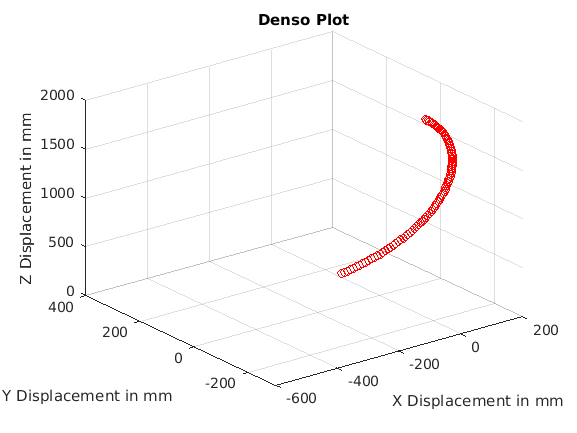


p = SolveH(H04);

DensoPlot(p)

##  Discussion

The results were  as expected. Problems 2-15 and 2-38 were refresher questions. The both tested challanged the knowledge of the previously studies questions but, in slightly different manner from its preceeding counterpart. This time, my work on paper was short hand which I used as reference when I began writing. I did run into an error where I mistakenly used $\theta$ instead of $\phi$ on the third problem but, it was easily noticable in the plot and I found it fairly quickly.

This time, I spent more time trying to figure out some clever code. I did manage to make some progress in simpifying the code by using more functions however, I was looking for a way to assign the values as a user with sliders. Unfortunately, I have not found enough information to utilize them but, I will continue to work on it.

Something I might have done differently, $O_3$ of problem three was a connection and not a joint. I think I could have considered it part of the link and ignored it connecting $O_2$ directly to $O_4$ 

I do have an animation I made in SolidWorks. Although it is diffucult to see, $d_4$ does not rotate or extend in any way.

 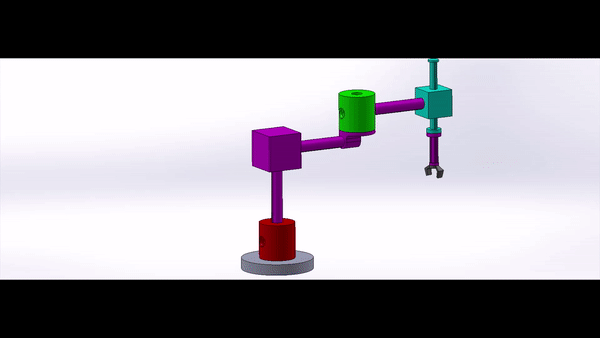

For this report, I believe the most difficult aspect was Preperation and Planning. The concepts were not new and much of the code was actually reused. The problem was in preperation and planning. It is important to be well organized before approaching a task, it is also important to actually start the task. There is a reasonable balance between planning and action. I am still working on that balance. 

## Reference

Denso Corperation. (2017). *DENSO Robotics Catalog*. DCatalog. https://html5.dcatalog.com/?docid=72c75621-8544-41b4-9afa-a7f60153efbd&page=32

Spong, M. W., Hutchinson, S., & Vidyasagar, M. (2020). *Robot Modeling and Control* (2nd ed.). Wiley.

### Functions

function EqualTo(R23, R12, R13)

    target = numel(R13);
    k = 0;
    
    Rc = R12*R23;

    for i = 1:height(R13)
        for j = 1:width(R13)
            if R13(i,j) == Rc(i,j)
                k = k+1;
            end
        end
    end


    if (k == target)
        disp('The Rotation Matrix of frame 3 with respect to frame 2 is correct.')
    end
    if(k ~= target)
        disp('The Rotation Matrix of frame 3 with respect to frame 2 is incorrect.')
    end
    
end

function h = TransformCombo(R,d)

    h = sym(zeros(4,4));
    h(4,4) = 1;
    
    for i = 1:height(R)
        for j = 1:width(R)
            h(i,j) = R(i,j);
        end
    end
    for m = 1:height(d)
        h(m,4) = d(m,1);
    end
    
end

function p = SolveH(H)
    t = [0:deg2rad(1):pi];
    ph = [0:deg2rad(.5):pi/2];
    di = [0:100/180:100];
    
    n = numel(di);
    p = zeros(n,3);
    
    for i = 1:n
        
        theta = t(1,i);
        phi = ph(1,i);
        Q = di(1,i);
        
        f = subs(H);
        
        p(1,i) = f(1,4);
        p(2,i) = f(2,4);
        p(3,i) = f(3,4);
    end
end

function DensoPlot(p)

    p1 = p(1,:);
    p2 = p(2,:);
    p3 = p(3,:);

    figure;
    while true
        for i = 1:181
            plot3(p1(1:i),p2(1:i),p3(1:i), 'or')
            title('Denso Plot')
            
            xlabel('X Displacement in mm')
            ylabel('Y Displacement in mm')
            zlabel('Z Displacement in mm')
            
            
            xlim([-600 200])
            ylim([-300 400])
            zlim([0 2000])
            
            grid on
            drawnow;
           
        end
    end
end